# Main

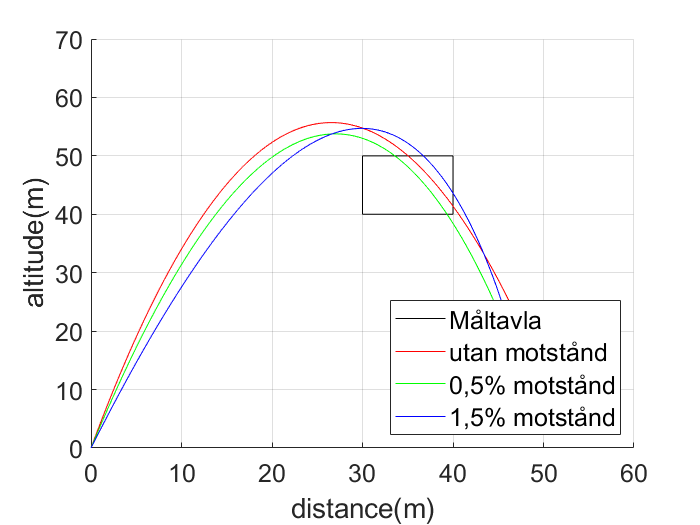

m = 8;
t = linspace(0,6);
g = 9.82; 

k = 0.00001;
k1 = 0.5;
k2 = 1.5;

a = pi/2.35;
a1 = pi/2.4; 
a2 = pi/2.5;

v0 = 34;
v01 = 36;
v02 = 42;

% utan luftmotstånd
[X, Y] = ode_ekv(m, k, v0, a, g, t);

% 0.5 luftmostånd
[X1, Y1] = ode_ekv(m, k1, v01, a1, g, t);

% 1.5 luftmostånd
[X2, Y2] = ode_ekv(m, k2, v02, a2, g, t);

% Fyrkantig måltavla 
square_x = [30 40 40 30 30];  
square_y = [40 40 50 50 40];

figure
grid on
hold on
plot(square_x, square_y,'black')
plot(X,Y, 'r')
plot(X1,Y1, 'g')
plot(X2,Y2, 'b')
xlabel('distance(m)','FontSize',15)
ylabel('altitude(m)','FontSize',15)
legend({'Måltavla','utan motstånd','0,5% motstånd','1,5% motstånd'},'FontSize',15,'Location','southeast');
axis([0 60 0 70])
set(gca,'FontSize',15)

## Uppgift 3, steg 7 & 8

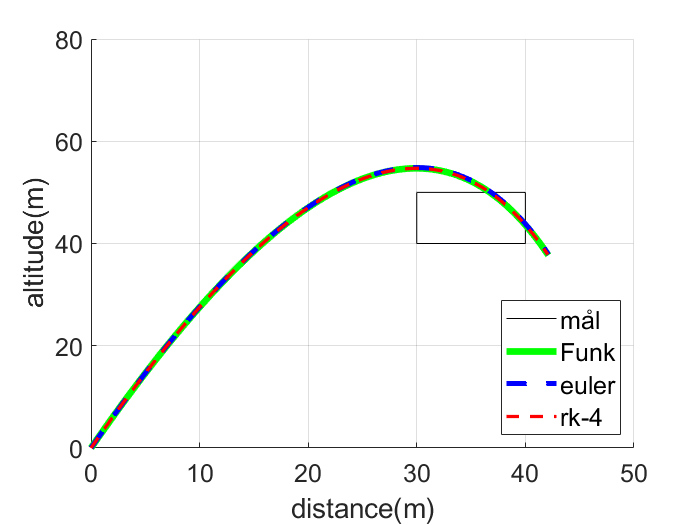

clear all

k = 1.5;
m = 8;
t = linspace(0,5,500);
g = 9.82;
a = pi/2.5;
v0 = 42;

square_x = [30 40 40 30 30];  
square_y = [40 40 50 50 40];

[X , Y] = ode_ekv(m, k, v0, a, g, t);
[t2,z2] = euler_solver(@funk_1, [0,5], [0 v0*cos(a) 0 v0*sin(a)], 500);
[z3,t3] = rk_4_solver(@funk_1, 0,5, [0 v0*cos(a) 0 v0*sin(a)], 500);
%[t4,z4] = ode45(@funk1, t2, [0 v0*cos(a) 0 v0*sin(a)]);

figure
grid on;
hold on;
plot(square_x, square_y,'black');
plot (X,Y,'g','LineWidth', 4);
plot (z2(1,:),z2(3,:),' -- b', 'LineWidth', 3);
plot (z3(1,:),z3(3,:),' -- r', 'LineWidth', 2);
xlabel('distance(m)','FontSize',15)
ylabel('altitude(m)','FontSize',15)
legend({'mål','Funk','euler','rk-4'},'FontSize',15,'Location','southeast')
%plot (z4(:, 1),z4(:, 3),'r','LineWidth', 1);
axis([0 50 0 80]);
set(gca,'FontSize',15)

## Uppgift 3, steg 9

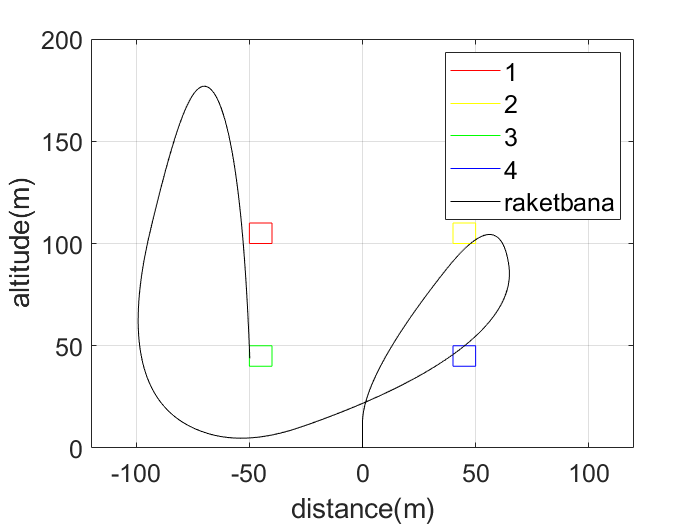

clear all

square_x_1 = [40 50 50 40 40];  
square_y_1 = [100 100 110 110 100];

square_x_3 = [40 50 50 40 40];
square_y_3 = [40 40 50 50 40];

square_x_2 = [-40 -50 -50 -40 -40];
square_y_2 = [40 40 50 50 40];

square_x_4 = [-40 -50 -50 -40 -40];
square_y_4 = [100 100 110 110 100];

%god speed cap'n
a = 3*pi/2;
v0 = 0;

[z,t]= rk_4_solver(@funk_2, 0,20, [0 v0*cos(a) 0 v0*sin(a)], 500);

figure


plot(square_x_4, square_y_4,'red')
hold on;
grid on;
plot(square_x_1, square_y_1,'yellow')
plot(square_x_2, square_y_2,'green')
plot(square_x_3, square_y_3,'blue')

plot (z(1,:),z(3,:), 'black');
%comet(z(1,:),z(3,:))

xlabel('distance(m)','FontSize',15)
ylabel('altitude(m)','FontSize',15)
legend({'1','2','3','4','raketbana'},'FontSize',15)
axis([-120 120 0 200])
set(gca,'FontSize',15)
hold off

## Plotta felet

clear all

k = 1.5;
m = 8;
t = linspace(0,5);
g = 9.82;
a = pi/2.5;
v0 = 42;

square_x = [40 50 50 40 40];  
square_y = [30 30 40 40 30];

[X , Y] = ode_ekv(m, k, v0, a, g, t);
[t2,z2] = euler_solver(@funk_1, [0, 5], [0 v0*cos(a) 0 v0*sin(a)], 100);
[z3,t3] = rk_4_solver(@funk_1, 0, 5, [0 v0*cos(a) 0 v0*sin(a)], 100);
[t4,z4] = ode45(@funk_1, t2, [0 v0*cos(a) 0 v0*sin(a)]);

E = abs(Y-z2(3,:));
R = abs(Y-z3(3,:));
O = abs(Y'-z4(:,3));

semilogy(z3(1,:), R, '--green','LineWidth',1)
hold on;
semilogy(z2(1,:), E, '--red','LineWidth',1)
semilogy(z4(:,1), O, '--black','LineWidth',1)
xlabel('X-values','FontSize',15)
ylabel('Fault','FontSize',15)
legend({'rk-4','euler','ode45', 'Location'},'FontSize',15,'Location','southeast')

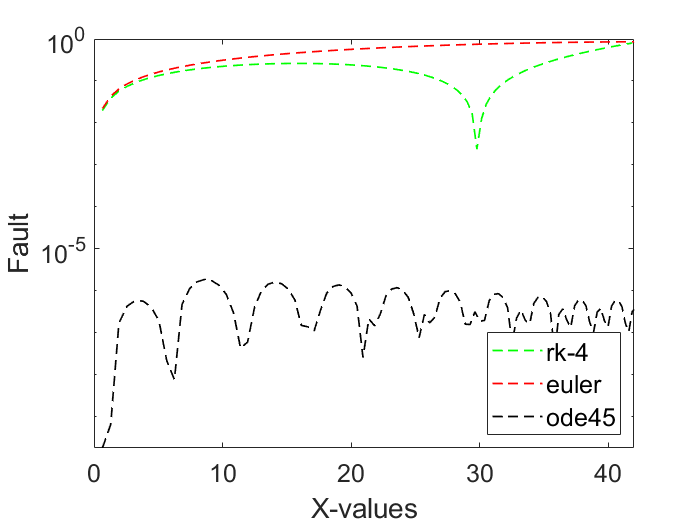

axis([0 42 0 1])
set(gca,'FontSize',15)
hold off

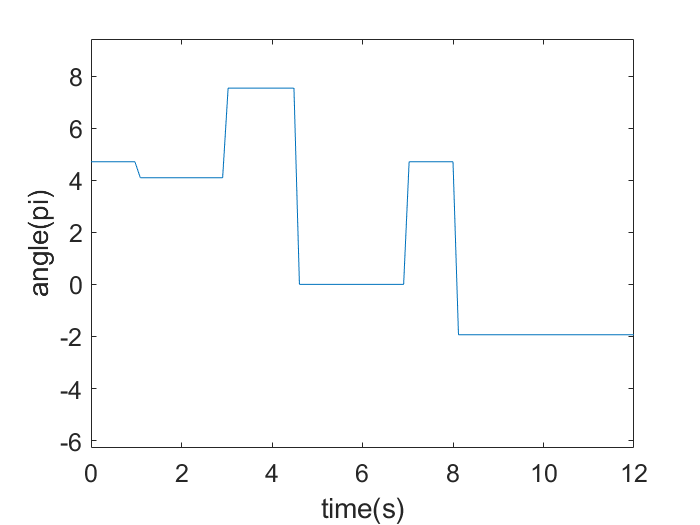

clear all
clf

X = linspace(0,12,100);
Y= zeros(1,100);
for i = 1:100
    Y(i) = jesus_take_the_wheel(X(i));
end

plot(X,Y)
xlabel('time(s)','FontSize',15)
ylabel('angle(pi)')
axis([0 12 -2*pi 3*pi])
set(gca,'FontSize',15)